# EXAMPLE: ZELDOVICH MECHANISM

It is desired to evaluate the nitric oxide (NO) emissions generated by the Zeldovich thermal mechanism in an Lean Premixed Prevaporized (LPP) gas turbine where a lean mixture of Fuel-Air is burned at constant pressure with a generic equivalence ratio $\phi$. The reactant mixture is compressed isentropically to enter the combustion chamber at $T_1 = 700 \ \text{K}$ and $p_1 = 10 \ \text{bar}$. Under these conditions, the mixture ignites, reacting adiabatically at constant pressure $p_1 =p_2 =p$ (HP chemical transformation) until reaching the adiabatic flame temperature $T_2 \left(\phi \right)$. Knowing that the average time that the mixture of products remains at the adiabatic temperature is about 10 ms, i.e., residence time $\tau_r = 10 \ \text{ms}$, it is requested to represent in the interval $0\ldotp 3\le \phi \le 1$:

- The mole fractions of the reactant mixture.

- The mole fractions of the product mixture. Assume incomplete combustion that takes into account the presence of H, O, and OH in the product mixture.

- The adiabatic flame temperature.

- The molar fraction of nitric oxide at the exit of the combustion chamber, $X_{\textrm{NO}}$.

- What is the maximum value of $\phi <1$ that allows guaranteeing a molar fraction of nitric oxide less than 50 ppm?

- Finally calculate the molar fraction of nitric oxide at the combustion chamber outlet assuming that NO is also in equilibrium, $X_{\textrm{NO},\;\textrm{eq}}$. Suppose for this incomplete combustion taking into account the presence of H, O, OH, and NO in the mixture of products. Compare the results obtained with those of section 5 and comment on the differences observed.

**NOTE:** This script uses ["Curves Intersection" - FileExchange](https://in.mathworks.com/matlabcentral/fileexchange/22441-curve-intersections).

**@author:** Alberto Cuadra Lara

                 Universidad Carlos III de Madrid

Last update March 22 2023

## Define case

% Fuel
Fuel = 'CH4'; 
% Temperature of the reactants [K]
TR = 700; 
% Pressure of the reactants [bar]
pR = 10;
% Equivalence ratio [-]
phi = 0.3:0.01:1;
% Residence time [s]
t_r = 10e-3; 

## 1. The mole fractions of the reactant mixture

**Initialize**

species = {'CO2', 'CO2', 'CO', 'H2O', 'H2', 'O2', 'N2', 'Ar', 'O', 'OH', 'H'};
self = App(species);

Loading NASA database ... OK!
NASA database with thermo loaded from main path ... OK!


**Set initial conditions**

% Set temperature, pressure, and equivalence ratio
self = set_prop(self, 'TR', TR, 'pR', pR, 'phi', phi);
% Set fuel
self.PD.S_Fuel = {Fuel};
% Set air as the oxidizer
self.PD.S_Oxidizer = {'N2', 'O2', 'Ar', 'CO2'};
% Composition relative to O2
self.PD.ratio_oxidizers_O2 = [78.084, 20.9476, 0.9365, 0.0319] / 20.9476;

**Set additional inputs**

% Set pressure of the products
self = set_prop(self, 'pP', self.PD.pR.value); 

**Miscellaneous**

% Do not print results in the command window
self.Misc.FLAG_RESULTS = false;
% Minimum value to show in molar fractions plots
self.C.mintol_display = 1e-4;

**Solve problems**

self = solve_problem(self, 'HP');

COMPUTING Nº MOLES FROM EQUIVALENCE RATIO (PHI).
Elapsed time is 0.959935 seconds
Elapsed time in the loop is 0.142567 seconds


**Get results**

% Get reactants
mix1 = self.PS.strR;
% Get products
mix2 = self.PS.strP;

**Plot mole fractions of the reactant mixture**

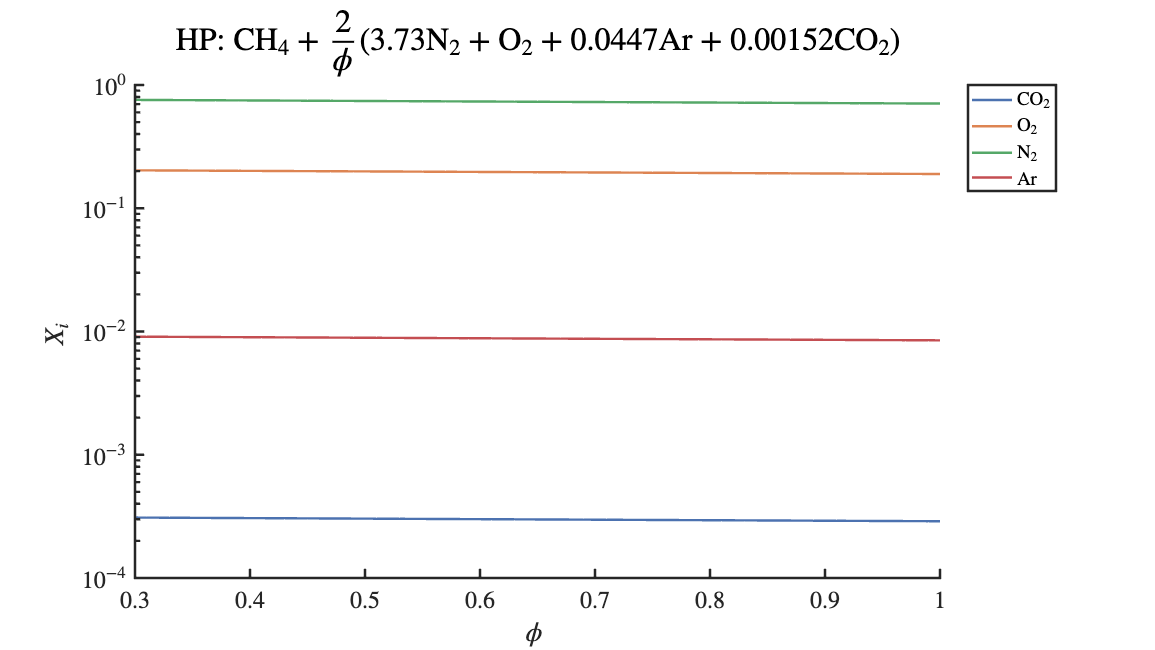

plot_molar_fractions(self, mix1, 'phi', 'Xi', 'ydata', mix1);

## 2. The mole fractions of the product mixture

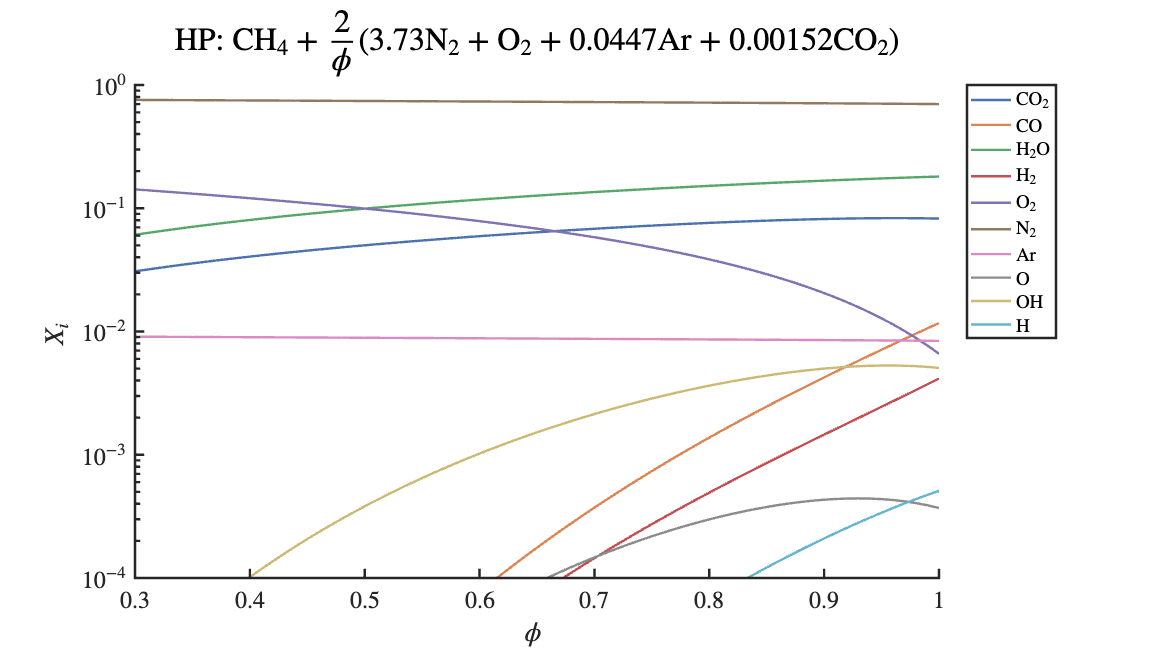

plot_molar_fractions(self, mix1, 'phi', 'Xi', 'ydata', mix2);

## 3. The adiabatic flame temperature

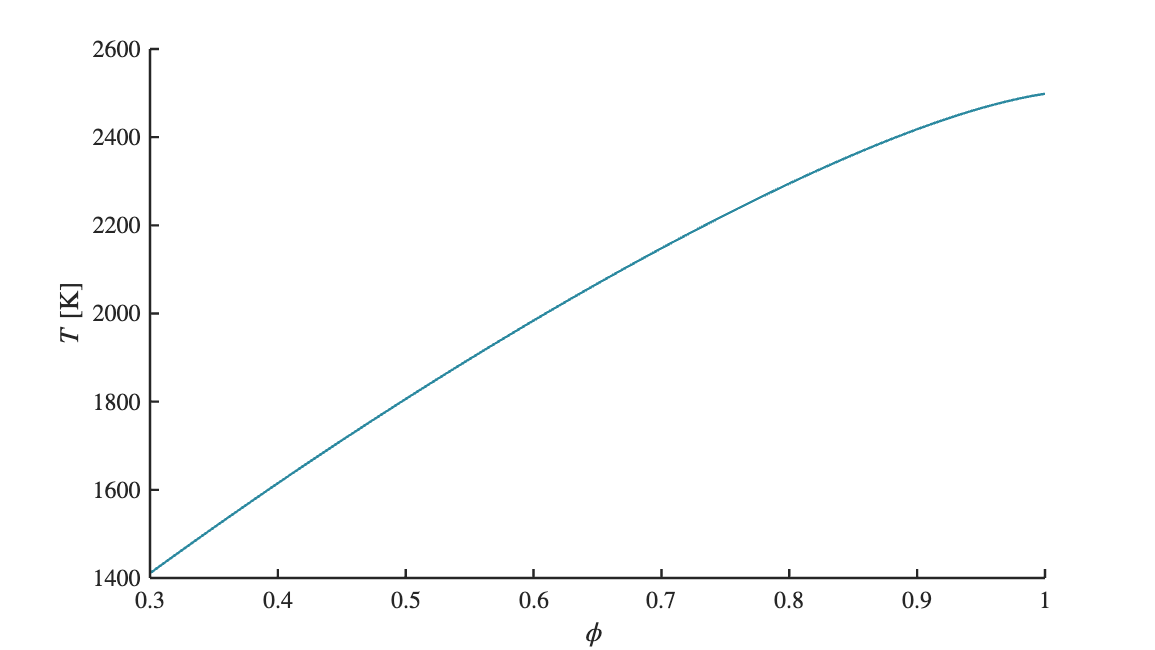

plot_figure('phi', phi, 'T', mix2, 'phi');

## 4. The molar fraction of nitric oxide at the exit of the combustion chamber, XNO

Compute NO using Zeldovich mechanism

% Universal gas constant [J/mol K]
R = self.C.R0;
% Pressure [Pa]
p = self.PD.pR.value * 1e5;
% Temperature of the products [K]
T = cell2vector(mix2, 'T');
% Concentration of the mixture == C_M = n_total / v = p / (R * T) 
C_M = (p ./ (R * T));       
% Molar fraction of the products [-]
molar_fractions = cell2vector(mix2, 'Xi');

% Get indeces N2, O
index_N2 = find_ind(self.S.LS, 'N2');
index_O = find_ind(self.S.LS, 'O');

% Get molar fractions of N2 and O
X_N2_eq = molar_fractions(index_N2, :);
X_O_eq = molar_fractions(index_O, :);

% Compute molar fraction of NO using Zeldovich mechanism
X_NO_zeld = 3.6e8 * exp(-38610 ./ T) .* C_M .* X_O_eq .* X_N2_eq .* t_r;

## 5. What is the maximum value of $\phi <1$ that allows guaranteeing a molar fraction of nitric oxide less than 50 ppm?

Compute intersection points (needs Curves Intersection - FileExchange)

% Set limit conditions (50 ppm of NO)
line_dashed_y = 50 * ones(1, length(self.PD.range));

% Compute intersection point limit emissions
P = InterX([phi; X_NO_zeld * 1e6], [phi; line_dashed_y]);
phi_critical = P(1,:);
X_NO_critical = P(2,:);

% Print values
fprintf('NOx critical value emissions for an equivalence ratio = %.4f\n', phi_critical);

NOx critical value emissions for an equivalence ratio = 0.6191


## 6. Finally calculate the molar fraction of nitric oxide at the combustion chamber outlet assuming that NO is also in equilibrium

**6.1 Compute composition at adiabatic temperature and composition at constant pressure with NO**

% Set list of species
species{end+1} = 'NO';

% Fast initialization
self = App('fast', self.DB_master, self.DB, species);

% Set initial conditions
self = set_prop(self, 'TR', TR, 'pR', pR, 'phi', phi);
self.PD.S_Fuel = {Fuel};
self.PD.S_Oxidizer = {'N2', 'O2', 'Ar', 'CO2'};
self.PD.ratio_oxidizers_O2 = [78.084, 20.9476, 0.9365, 0.0319] / 20.9476;

% Set additional inputs
self = set_prop(self, 'pP', self.PD.pR.value); 

% Miscellaneous
self.Misc.FLAG_RESULTS = false; % Do not print results in the command window
self.C.mintol_display = 1e-4; % Minimum value to show in molar fractions plots

% Solve problems
self = solve_problem(self, 'HP');

COMPUTING Nº MOLES FROM EQUIVALENCE RATIO (PHI).
Elapsed time is 0.148914 seconds
Elapsed time in the loop is 0.138642 seconds


% Get results
mix1 = self.PS.strR;
mix2 = self.PS.strP;

molar_fractions = cell2vector(mix2, 'Xi'); % Molar fraction of the products [-]
index_NO = find_ind(self.S.LS, 'NO');
X_NO_eq = molar_fractions(index_NO, :);

**6.2 Compute intersection point limit validity of Zeldovich mechanism. Obtaining the chemical characteristic time of NO**

% Estimate chemical characteristic time of NO
k1 = 1.8e8 * exp(-38610 ./ T); % [m3 / (mol s)]
dX_NOdt = 2 * k1 .* C_M .* X_N2_eq .* X_O_eq; % [1 / s]
t_NO = X_NO_eq ./ dX_NOdt; % [s] or equivalently tau_c = (1 / t_r * X_NO_zeld ./ X_NO_eq).^(-1)

% Compute intersection point with residence time
P = InterX([phi; t_NO], [[phi(1), phi(end)]; [10, 10] * 1e-3]);
phi_tau_eq = P(1,:);
tau_eq = P(2,:);

% Print critical value
fprintf('Chamber outlet at equilibrium for an equivalence ratio = %.4f\n', phi_tau_eq);

Chamber outlet at equilibrium for an equivalence ratio = 0.8844


**Plot results**

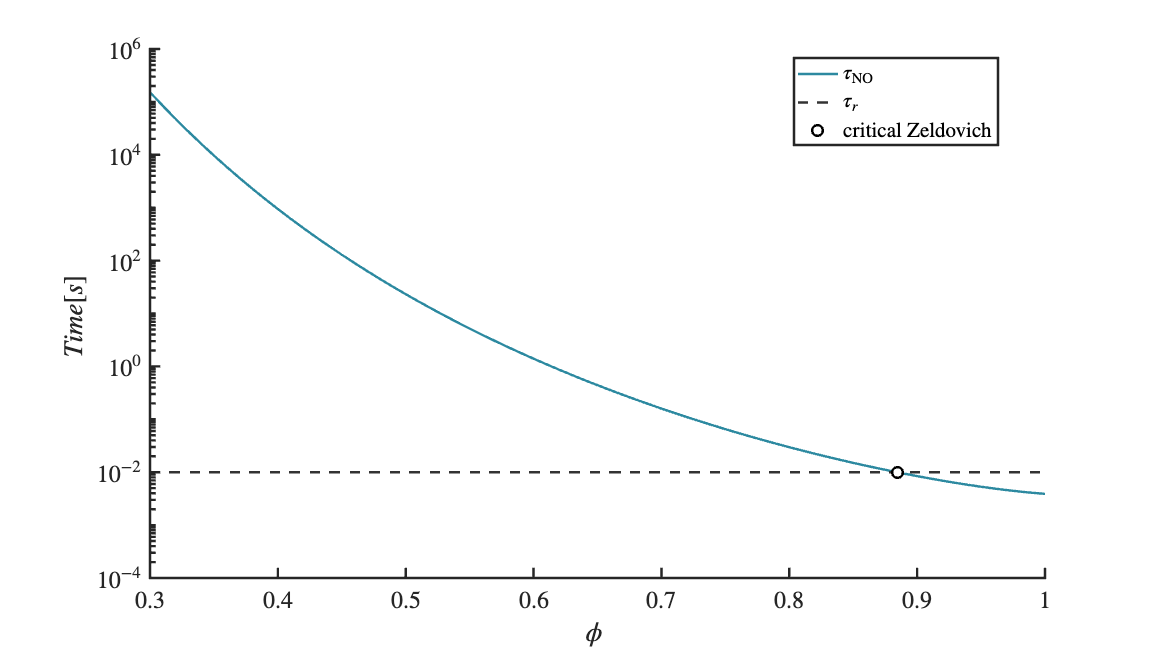

% Configure figure
self.Misc.config.yscale = 'log';
ax = set_figure(self.Misc.config);

% Plot results
ax = plot_figure('phi', phi, 'Time [s]', t_NO, 'ax', ax);
ax = plot_figure('phi', ax.XLim, 'Time [s]', [10, 10] * 1e-3, 'linestyle', '--', 'ax', ax, 'color', [0.2, 0.2, 0.2]);
plot(ax, phi_tau_eq, tau_eq, 'o', 'LineWidth', self.Misc.config.linewidth, 'MarkerFaceColor', 'auto', 'MarkerEdgeColor', 'black', 'MarkerSize', 8);
% Set legends
legend_labels = {'$\tau_{\rm NO}$', '$\tau_r$', 'critical Zeldovich'};
set_legends(ax, legend_labels);

**6.3 Compute intersection point limit validity of Zeldovich mechanism. Equilibrium achieved in the chamber.**

P = InterX([phi; X_NO_zeld * 1e6], [phi; X_NO_eq * 1e6]);
phi_zeld_eq = P(1,:);
X_NO_zeld_eq = P(2,:);

% Print critical value
fprintf('Chamber outlet at equilibrium for an equivalence ratio = %.4f\n', phi_zeld_eq);

Chamber outlet at equilibrium for an equivalence ratio = 0.8841


**Plot results**

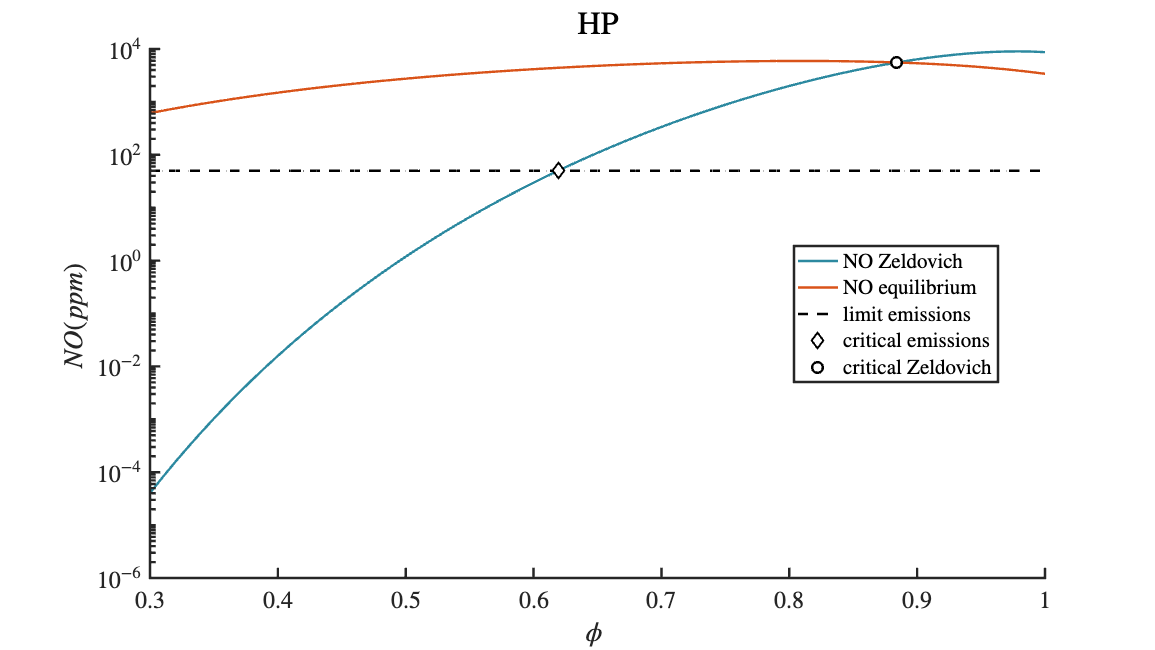

% Configure plot
self.Misc.config.labely = 'NO (ppm)';
self.Misc.config.title = strrep(self.PD.ProblemType, '_', ' ');
% Plot ppm of NO obtained with the mechanism of Zeldovich and
% considering chemical equilbrium
ax = plot_figure('phi', phi, 'NO (ppm)', X_NO_zeld * 1e6, 'config', self.Misc.config);
ax = plot_figure('phi', phi, 'NO (ppm)', X_NO_eq * 1e6, 'config', self.Misc.config, 'ax', ax, 'color', 'auto');
% Plot critical value and limit line
plot(ax, phi, line_dashed_y, '--k', 'LineWidth', self.Misc.config.linewidth);
plot(ax, phi_critical, X_NO_critical, 'd', 'LineWidth', self.Misc.config.linewidth, ...
    'MarkerFaceColor', 'auto', 'MarkerEdgeColor', 'black', 'MarkerSize', 8);
plot(ax, phi_zeld_eq, X_NO_zeld_eq, 'o', 'LineWidth', self.Misc.config.linewidth, ...
    'MarkerFaceColor', 'auto', 'MarkerEdgeColor', 'black', 'MarkerSize', 8);
set(ax,'yscale','log');

% Set legends
legend_labels = {'NO Zeldovich', 'NO equilibrium', 'limit emissions', 'critical emissions', 'critical Zeldovich'};
set_legends(ax, legend_labels);